# **변경사항**

## 미완성

# **주의**

## (2) 경로 추가 관련

시작 전에, 이 파일이 들어 있는 폴더를 matlab 경로에 추가해 주세요.

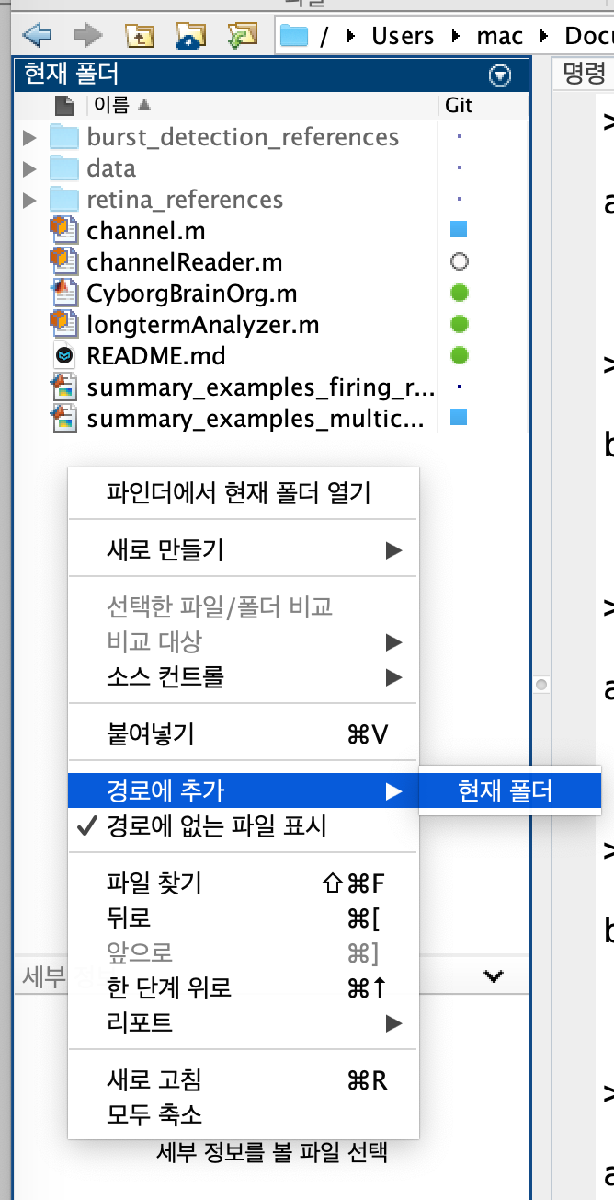

### **0.1. time variable이 없는 retina data 불러와 channel object 만들기**

**parameter 5개**

- `filename`: 이 파일(mlx)와 같은 디렉토리에 데이터 파일이 있을 경우 그 파일이름만, 다른 디렉토리에 있을 경우 전체 경로 포함 입력. 단, 이 파일(mlx)가 있는 폴더의 하위 디렉토리일 경우 현재 폴더까지의 경로는 ./로 줄여 표현 가능(아래 예제 코드 참고)

- `sampleRate` : 데이터 측정 sampling rate(Hz)

- `organoid`**:** organoid 번호 (관리를 위한 번호, 제한 없음) 

- `channel`: channel 번호 (관리를 위한 번호, 제한 없음) 

- `month`: month. 나중에 month별로 종합할 때 사용됨 (관리를 위한 번호, 제한 없음)

chr = channelReader(); %channelReader object 생성
%                                         filename, sampleRate, organoid, channel, month 
data1 = chr.readRetinaWithoutTime("./data/Data 1.csv", 3152, 1,1,1);

파일의 마지막 열이 모두 공백 문자로 되어 있습니다. matlab은 공백 문자를 NaN으로 불러옵니다. 해당 열을 삭제했습니다.


### **0.2. time variable이 있는 retina data 불러와 channel object 만들기**

**parameter 4개**

- `filename`: 이 파일(mlx)와 같은 디렉토리에 데이터 파일이 있을 경우 그 파일이름만, 다른 디렉토리에 있을 경우 전체 경로 포함 입력. 단, 이 파일(mlx)가 있는 폴더의 하위 디렉토리일 경우 현재 폴더까지의 경로는 ./로 줄여 표현 가능(아래 예제 코드 참고)

- `organoid`**:** organoid 번호 (관리를 위한 번호, 제한 없음) 

- `channel`: channel 번호 (관리를 위한 번호, 제한 없음) 

- `month`: month. 나중에 month별로 종합할 때 사용됨 (관리를 위한 번호, 제한 없음)

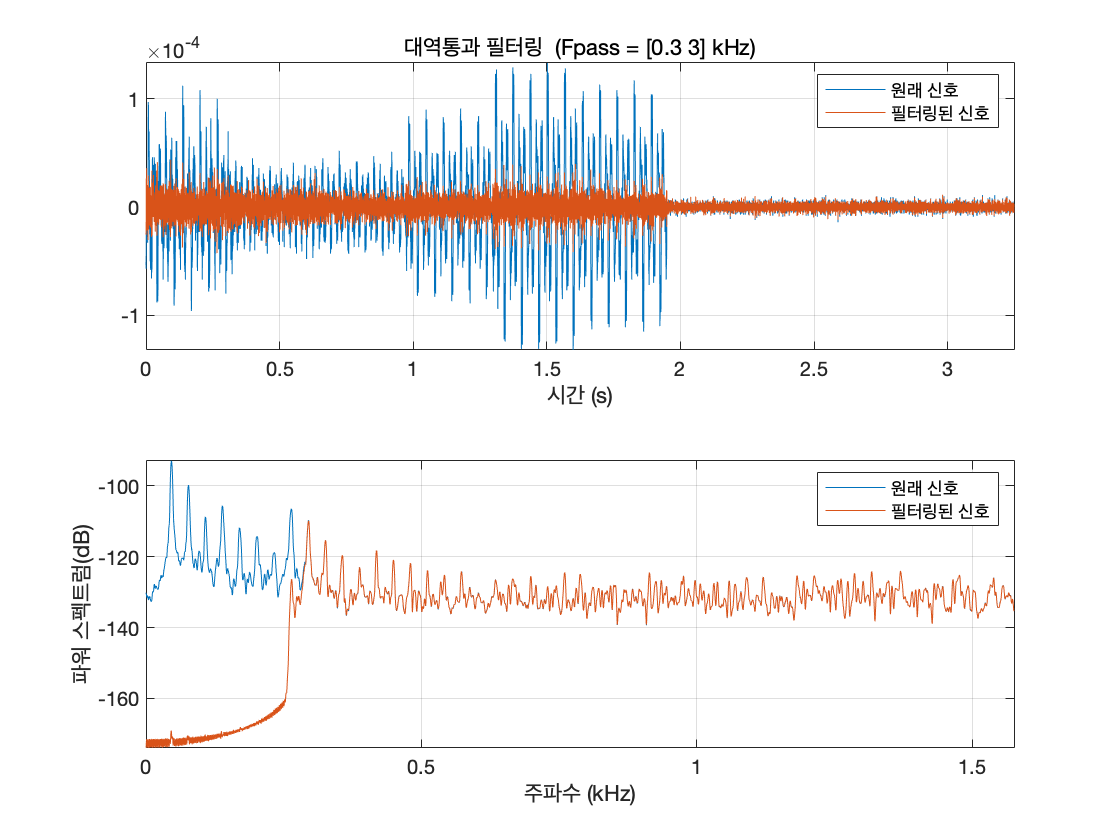

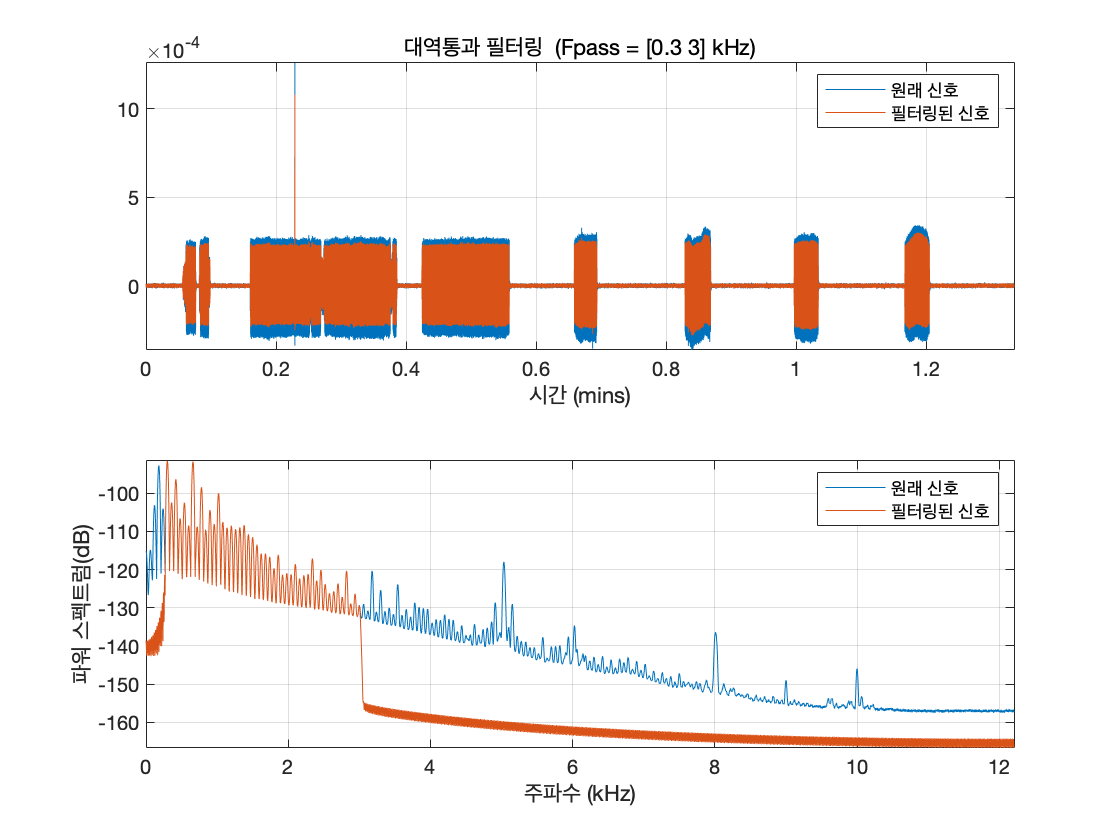

%                                                                                      filename, organoid, channel, month 
data2 = chr.readRetinaWithTime("./data/Data 3.csv", 1,1,1);

### **0.3 bandpass filter preview**

channel object에서 raw 데이터를 불러와서 bandpass filter 적용시 어떤 결과가 나오는지 그래프로 확인

#### data 1.csv

%apply bandpass filter 300-3000hz
bandpass(data1.raw, [300,3000], data1.sf)

#### data 2.csv

bandpass(data2.raw, [300,3000], data2.sf)

### **0.4. bandpass filter 적용**

**파라미터 1개 **

- `passBand` : [숫자, 숫자] 포맷으로, hz 단위로 입력

 bandpass filter 실제로 적용하여 channel object 내에 저장

data1.bandPass([300,3000]); %apply bandpass filter 300-3000hz
data2.bandPass([300,3000]); %apply bandpass filter 300-3000hz

number of spikes found : 209


number of spikes found : 12



 In the (1, 1)th pixel,
Added a channel object with 209 spikes, timerange 0 - 3.248414e+00(s) 
 Current total number of channels = 1
Added a channel object with 12 spikes, timerange 0 - 1.006592e+00(s) 
 Current total number of channels = 2



 In the (1, 2)th pixel,
Added a channel object with 209 spikes, timerange 0 - 3.248414e+00(s) 
 Current total number of channels = 1
Added a channel object with 209 spikes, timerange 0 - 3.248414e+00(s) 
 Current total number of channels = 2



 In the (1, 3)th pixel,
Added a channel object with 12 spikes, timerange 0 - 1.006592e+00(s) 
 Current total number of channels = 1
Added a channel object with 12 spikes, timerange 0 - 1.006592e+00(s) 
 Current total number of channels = 2


### **0.5. (method) **`detectSpikes`

**spike detection 수행**

**paramter 3개**

- `thres`: spike 분류 기준. 5를 입력하면 평균+5표준편차 밖의 값을 spike로 분류 ((reference code에서는 5)

- `preTime`: spike waveform의 spike 앞쪽 너비. milisecond 단위 (reference code에서는 2)

- `postTime`: spike waveform의 spike 뒷쪽 너비. milisecond 단위 (reference code에서는 2)

주의: 코드 내 threshold에 minus가 붙어 있음, 즉 이 알고리즘은 local minimum을 찾는 알고리즘. 레퍼런스 코드에서 이렇게 구현되어 있었음.

                        %thres, preTime, postTime


 In the (2, 1)th pixel,
Added a channel object with 209 spikes, timerange 0 - 3.248414e+00(s) 
 Current total number of channels = 1
Added a channel object with 209 spikes, timerange 0 - 3.248414e+00(s) 
 Current total number of channels = 2


data1.detectSpikes(3,2,2);


 In the (2, 2)th pixel,
Added a channel object with 209 spikes, timerange 0 - 3.248414e+00(s) 
 Current total number of channels = 1
Added a channel object with 12 spikes, timerange 0 - 1.006592e+00(s) 
 Current total number of channels = 2


data2.detectSpikes(3,2,2);


 In the (2, 3)th pixel,
Added a channel object with 12 spikes, timerange 0 - 1.006592e+00(s) 
 Current total number of channels = 1
Added a channel object with 209 spikes, timerange 0 - 3.248414e+00(s) 
 Current total number of channels = 2



 In the (3, 1)th pixel,
Added a channel object with 12 spikes, timerange 0 - 1.006592e+00(s) 
 Current total number of channels = 1
Added a channel object with 12 spikes, timerange 0 - 1.006592e+00(s) 
 Current total number of channels = 2



 In the (3, 2)th pixel,
Added a channel object with 209 spikes, timerange 0 - 3.248414e+00(s) 
 Current total number of channels = 1
Added a channel object with 12 spikes, timerange 0 - 1.006592e+00(s) 
 Current total number of channels = 2


ani = animatedPixelMaker(3,3);


 In the (3, 3)th pixel,
Added a channel object with 209 spikes, timerange 0 - 3.248414e+00(s) 
 Current total number of channels = 1
Added a channel object with 209 spikes, timerange 0 - 3.248414e+00(s) 
 Current total number of channels = 2


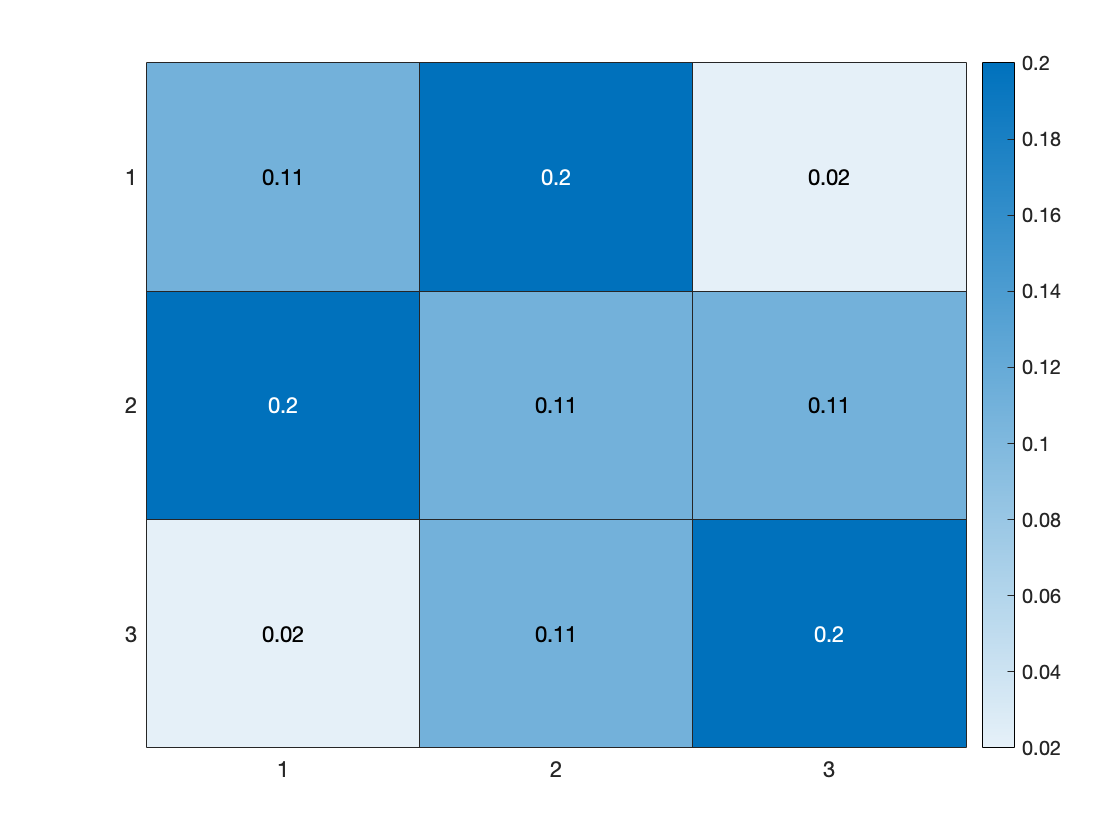

ani.addPixel(1,1, data1, data2)
ani.addPixel(1,2, data1, data1)

ani.addPixel(1,3, data2, data2)
ani.addPixel(2,1, data1, data1)
ani.addPixel(2,2, data1, data2)
ani.addPixel(2,3, data2, data1)
ani.addPixel(3,1, data2, data2)
ani.addPixel(3,2, data1, data2)
ani.addPixel(3,3, data1, data1)
ani.preProcess(1e-5, 100)
ani.makeAnimatedPixels()


파일의 마지막 열이 모두 공백 문자로 되어 있습니다. matlab은 공백 문자를 NaN으로 불러옵니다. 해당 열을 삭제했습니다.
